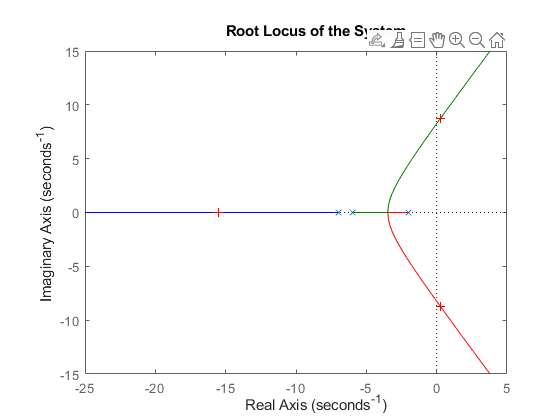

Select a point in the graphics window


selected_point = -14.6564 + 3.9938i

% Define the transfer function
s = tf('s');
G = 127/((s+6)*(s+7)*(s+2));

% Plot the root locus
figure;
rlocus(G);
title('Root Locus of the System');

% Use rlocfind to select a point on the root locus plot
[k, poles] = rlocfind(G);


% Display the selected gain and pole location
disp(['Selected Gain: ', num2str(k)]);

Selected Gain: 8.6029


disp(['Pole Location: ', num2str(poles)]);

Error using horzcat
Dimensions of arrays being concatenated are not consistent.


% Calculate and display damping ratio, overshoot, and natural frequency
for i = 1:length(poles)
    zeta = -real(poles(i))/abs(poles(i));
    wn = abs(poles(i));
    PO = exp((-pi * zeta) / sqrt(1 - zeta^2)) * 100;

    disp(['Pole ', num2str(i), ':']);
    disp(['  Damping Ratio: ', num2str(zeta)]);
    disp(['  Natural Frequency: ', num2str(wn), ' rad/s']);
    disp(['  Percent Overshoot: ', num2str(PO), '%']);
end